%% RUN_DIM_REDUCTION_EXPERIMENT.M - 特征降维对比实验自动化脚本
% 功能: 
% 1. 读取音频并提取全量 49维特征
% 2. 自动测试不同特征组合 (MFCC vs 全特征 vs 频谱特征)
% 3. 生成对比报表，帮你决定到底用多少维
% -------------------------------------------------------------------------
clear; close all; clc;

disp('==========================================================');

disp('🧪 声纹锁特征降维与鲁棒性测试实验 (Dimensionality Reduction)');

🧪 声纹锁特征降维与鲁棒性测试实验 (Dimensionality Reduction)


disp('==========================================================');


% --- 1. 准备数据 (交互式获取) ---
% 建议：第一次先选“干净语音”，跑个基准；
%       第二次选“加噪/混响语音”，看看降维后的抗噪效果。
disp('请选择 [Speaker A (本人)] 的音频文件...');

请选择 [Speaker A (本人)] 的音频文件...


Files_A = get_file_list_ui('选择 Speaker A 文件');

>> 选择 Speaker A 文件



disp('请选择 [Speaker B (他人)] 的音频文件...');

请选择 [Speaker B (他人)] 的音频文件...


Files_B = get_file_list_ui('选择 Speaker B 文件');

>> 选择 Speaker B 文件



if isempty(Files_A) || isempty(Files_B)
    error('未选择文件，实验终止。');
end

% --- 2. 提取全量特征 (一次性完成) ---
disp(' ');

disp('🚀 正在提取全量 49维特征 (作为特征池)...');

🚀 正在提取全量 49维特征 (作为特征池)...



% 提取 A 组特征
Features_A = {};
for i = 1:length(Files_A)
    try
        feat = extract_voice_features(Files_A{i});
        if ~isempty(feat), Features_A{end+1} = feat; end
    catch
        warning(['文件提取失败: ' Files_A{i}]);
    end
end

% 提取 B 组特征
Features_B = {};
for i = 1:length(Files_B)
    try
        feat = extract_voice_features(Files_B{i});
        if ~isempty(feat), Features_B{end+1} = feat; end
    catch
        warning(['文件提取失败: ' Files_B{i}]);
    end
end

if length(Features_A) < 2 || isempty(Features_B)
    error('有效特征不足 (A组需>=2, B组需>=1)，请检查文件或预处理模块。');
end

disp(['✅ 特征提取完毕! A组有效: ', num2str(length(Features_A)), ', B组有效: ', num2str(length(Features_B))]);

✅ 特征提取完毕! A组有效: 35, B组有效: 15




% --- 3. 定义实验组 (切蛋糕) ---
% 这里定义你想对比的维度组合
experiments = struct();
idx = 1;

% [组1] 只用 MFCC (最基础, 12维)
experiments(idx).name = '仅MFCC (12维)';
experiments(idx).dims = 1:12; 
idx = idx+1;

% [组2] MFCC + 差分 (经典组合, 24维) -> *重点关注*
experiments(idx).name = 'MFCC+Delta (24维)';
experiments(idx).dims = 1:24; 
idx = idx+1;

% [组3] 仅频谱特征 (25维) -> 用来测试它是不是“猪队友”
experiments(idx).name = '仅频谱特征 (25维)';
experiments(idx).dims = 25:49; 
idx = idx+1;

% [组4] 全家桶 (49维)
experiments(idx).name = '全特征融合 (49维)';
experiments(idx).dims = 1:49; 
idx = idx+1;


% --- 4. 循环跑实验 ---
disp(' ');

disp('⚔️  开始多维度对比测试...');

⚔️  开始多维度对比测试...


disp('-------------------------------------------------------------------------------');

-------------------------------------------------------------------------------


fprintf('%-20s | %-12s | %-12s | %-12s\n', '特征组合', '类内距离(↓)', '类间距离(↑)', '区分度(Ratio ↑)');

特征组合                 | 类内距离(↓)      | 类间距离(↑)      | 区分度(Ratio ↑)


disp('-------------------------------------------------------------------------------');

-------------------------------------------------------------------------------



results = [];

for k = 1:length(experiments)
    exp_name = experiments(k).name;
    dim_idx  = experiments(k).dims;
    
    % --- 核心逻辑: 特征切片 ---
    % 将 cell 数组里的每个矩阵都切一刀
    Sub_Feats_A = cellfun(@(x) x(dim_idx, :), Features_A, 'UniformOutput', false);
    Sub_Feats_B = cellfun(@(x) x(dim_idx, :), Features_B, 'UniformOutput', false);
    
    % --- 计算距离分布 ---
    [d_intra, d_inter] = calculate_distances(Sub_Feats_A, Sub_Feats_B);
    
    % --- 统计指标 ---
    mu_intra = mean(d_intra); % 越小越好 (自己和自己像)
    mu_inter = mean(d_inter); % 越大越好 (别人和我不像)
    
    % 区分度 Ratio (简单定义为 Inter / Intra)，越大越好
    if mu_intra < 1e-6, ratio = Inf; else, ratio = mu_inter / mu_intra; end
    
    % 打印一行结果
    fprintf('%-20s | %10.4f   | %10.4f   | %10.4f\n', exp_name, mu_intra, mu_inter, ratio);
    
    % 保存绘图用
    results(k).name = exp_name;
    results(k).d_intra = d_intra;
    results(k).d_inter = d_inter;
end

仅MFCC (12维)          |     1.9882   |     2.2162   |     1.1147
MFCC+Delta (24维)     |     1.9917   |     2.2187   |     1.1140
仅频谱特征 (25维)          |     8.5853   |     9.8059   |     1.1422
全特征融合 (49维)          |     8.8332   |    10.0722   |     1.1403


disp('-------------------------------------------------------------------------------');

-------------------------------------------------------------------------------


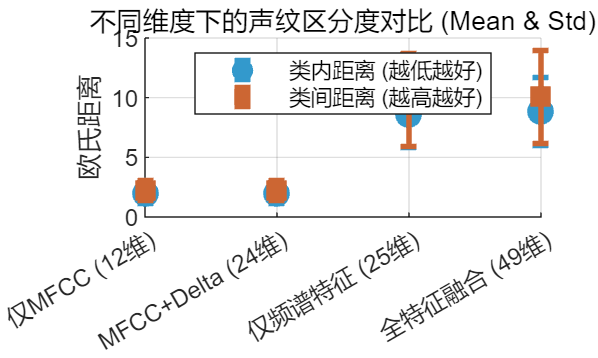



% --- 5. 可视化对比 (箱线图) ---
figure('Name', '特征降维性能对比', 'Position', [100, 100, 1000, 600]);
hold on;
group_labels = {};
plot_data = [];
group_idx = [];

% 整理数据给 boxplot
color_intra = [0.2, 0.6, 0.8]; % 蓝
color_inter = [0.8, 0.4, 0.2]; % 红

positions = [];
for k = 1:length(experiments)
    % 构造位置: 组1在 1,2; 组2在 4,5 ...
    pos_intra = (k-1)*4 + 1;
    pos_inter = (k-1)*4 + 2;
    
    % 绘制箱线图 (手动叠加数据太麻烦，这里用简化版)
    % 实际上我们画两组分布的均值和方差可能更直观
    
    % 这里用 Errorbar 画均值和标准差
    errorbar(k, mean(results(k).d_intra), std(results(k).d_intra), 'o', ...
        'Color', color_intra, 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', color_intra);
    errorbar(k, mean(results(k).d_inter), std(results(k).d_inter), 's', ...
        'Color', color_inter, 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', color_inter);
end

set(gca, 'XTick', 1:length(experiments), 'XTickLabel', {experiments.name});
legend('类内距离 (越低越好)', '类间距离 (越高越好)', 'Location', 'Best');
title('不同维度下的声纹区分度对比 (Mean & Std)');
ylabel('欧氏距离');
grid on;


disp('🎉 实验完成！请根据 [区分度 Ratio] 决定保留哪组特征。');

🎉 实验完成！请根据 [区分度 Ratio] 决定保留哪组特征。




% -----------------------------------------------------------
% 辅助函数
% -----------------------------------------------------------

function files = get_file_list_ui(prompt_str)
    % 简化的文件选择器
    disp(['>> ' prompt_str]);
    [fname, fpath] = uigetfile({'*.wav;*.flac'}, prompt_str, 'MultiSelect', 'on');
    if isequal(fname, 0), files = {}; return; end
    if ischar(fname), fname = {fname}; end
    files = fullfile(fpath, fname);
end

function [d_intra, d_inter] = calculate_distances(SetA, SetB)
    % 计算类内距离 (A vs A)
    d_intra = [];
    for i = 1:length(SetA)
        for j = i+1:length(SetA)
            d = feature_analysis_tool(SetA{i}, SetA{j}); % 调用你的距离工具
            d_intra = [d_intra, d];
        end
    end
    
    % 计算类间距离 (A vs B)
    d_inter = [];
    for i = 1:length(SetA)
        for j = 1:length(SetB)
            d = feature_analysis_tool(SetA{i}, SetB{j});
            d_inter = [d_inter, d];
        end
    end
end